clear all
clc
n = 12;
Sb = 100e6;

datos_linea = [4 5 0.01 1j*0.068 1j*0.0348; 
               4 6 0.017 1j*0.092 1j*0.0549; 
               5 7 0.011308 1j*0.02832 1j*0.0317638; 
               6 9 0.039 1j*0.1738 1j*0.0358; 
               6 12 0.023 1j*0.18 1j*0.0236; 
               7 8 0.008477 1j*0.057522 1j*0.158821; 
               8 9 0.0119 1j*0.1008 1j*0.0209; 
               10 11 0.031 1j*0.123 1j*0.0123];
           
X_tridevanado = [0.06 0.07 0.025; 350e6 200e6 150e6];
Xpst = Impedancias_tridevanado(X_tridevanado, Sb);

%Barra1 Barra 2 X12 tapmax pasos_tap delta1 

% datos_trafos = [1 4 1j*Xpst(1) 0.1 0.02 0; 
%                 4 10 1j*Xpst(2) 0.1 0.02 0; 
%                 1 10 1j*Xpst(3) 0.1 0.02 330; 
%                 2 7 1j*0.011 0 0 30; 
%                 3 9 1j*0.073 0 0 -30; 
%                 11 12 1j*0.22 0.1 0.02 -30];

%Barra1 Barra2 Barra3 X1 X2 X3 tapmax pasos_tap delta1 delta2 
datos_trafos = [1 4 10 1j*Xpst(1) 1j*Xpst(2) 1j*Xpst(3) 0.1 0.02 0 330; 
                2 7 0 1j*0.05 0 0 0 0 30 0; 
                3 9 0 1j*0.08 0 0 0 0 -30 0; 
                11 12 0 1j*0.1 0 0 0.1 0.02 -30 0];

disp('Info del sistema')

Info del sistema


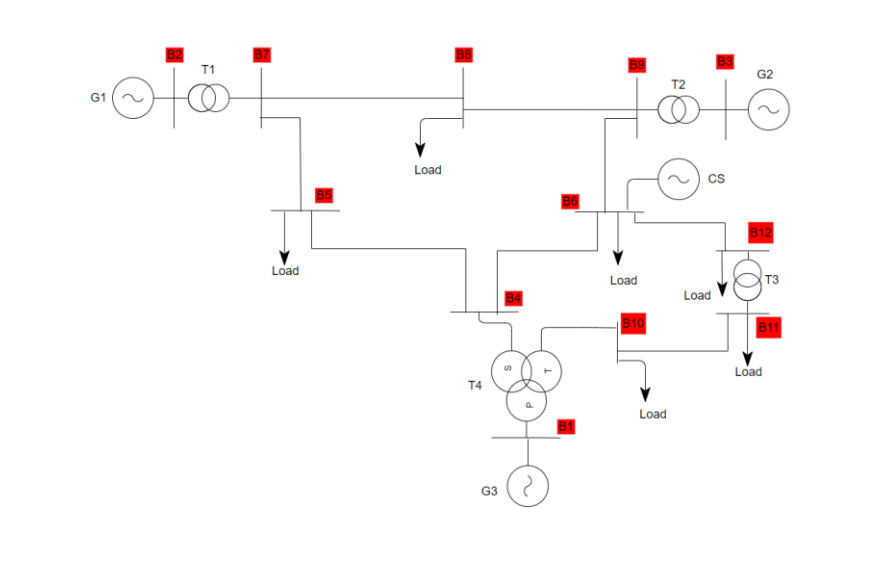

SP = imread('Sistema_potencia_ejp.png');
imshow(SP)

disp('Líneas : ')

Líneas : 


for i = 1:length(datos_linea(:,1))
    l = ['Linea ', num2str(i), ': ', num2str(datos_linea(i,1)), ' - ', num2str(datos_linea(i,2))];
    disp(l)
end

Linea 1: 4 - 5
Linea 2: 4 - 6
Linea 3: 5 - 7
Linea 4: 6 - 9
Linea 5: 6 - 12
Linea 6: 7 - 8
Linea 7: 8 - 9
Linea 8: 10 - 11


disp('Trafos: ')

Trafos: 


for i = 3:length(datos_trafos(:,1))
    if i == 3
        l = ['Trafo ', num2str(1), ' : ', num2str(datos_trafos(1,1)), ' - ', num2str(datos_trafos(2,1)), ' - ', num2str(datos_trafos(3,1)), ' -- ', 'LTC : ', num2str(datos_trafos(1,4)), '/', num2str(datos_trafos(1,5))];
    elseif datos_trafos(i,4)  ~= 0
        l = ['Trafo ', num2str(i-2), ' : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2)),' -- ', 'LTC : ', num2str(datos_trafos(i,4)), '/', num2str(datos_trafos(i,5))];
    else 
        l = ['Trafo ', num2str(i-2), ' : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2))];
    end
    disp(l)
end

Trafo 1 : 1 - 2 - 3 -- LTC : 0-0.00059524i/0+0.017738i
Trafo 2 : 11 - 12 -- LTC : 0+0.1i/0


LTC = datos_trafos(datos_trafos(:,4) ~= 0, :);

**GENERADORES**

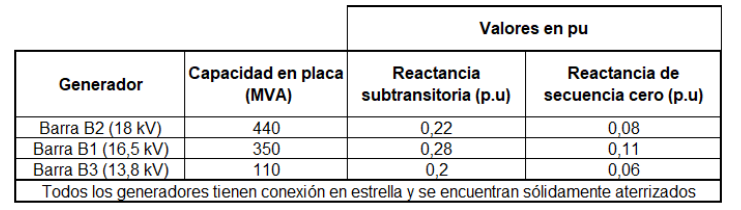

Sg2 = 440e6;
Sg1 = 350e6;
Sg3 = 110e6;

**ESCENARIOS DE CARGA**

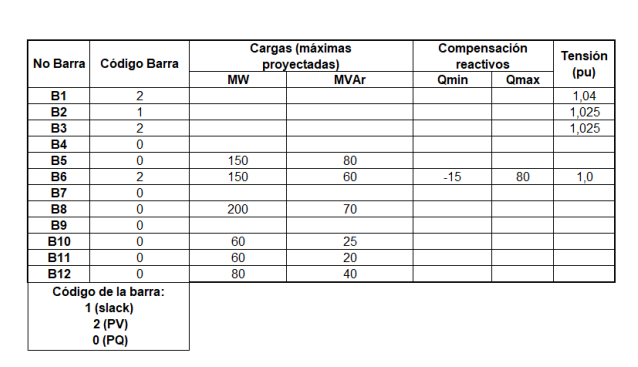

**PLENA CARGA**

clc
pasos = [];
count = 1;
for i = 3:length(LTC(:,1))
    if i == 3
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(1,1)), ' - ', num2str(LTC(2,1)), ' - ', num2str(LTC(3,1)), '? \n'];
    else
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(i,1)), ' - ', num2str(LTC(i,2)), '? \n'];
    end
    Q2 = input(ltc);
    pasos(count) = Q2;
    count = count+1;
end
%Pasos óptimos 3, -1
[y_barra, r2p, r3p] = Matriz_Ybarra3(datos_linea,n,datos_trafos,pasos);
% 0 -> Slack; 1 -> PV; 2 -> PQ
%[Barra Tipo Pgen Qgen Pd Qd Qmin Qmax V delta]
datos_potencia_PC = [2  0 false false false false 0 0 1.025 0;
                  1  1 (350e6)*0.77 false false false -100*Sb 100*Sb 1.04 0; 
                  3  1 (110e6)*0.76 false false false -100*Sb 100*Sb 1.025 0; 
                  4  2 false false false false false false 1 0; 
                  5  2 false false (150e6)*0.7 (80e6)*0.7 false false 1 0; 
                  6  1 false false (150e6)*0.7 (60e6)*0.7 -15e6 80e6 1 0; 
                  7  2 false false false false false false 1 0; 
                  8  2 false false (200e6)*0.7 (70e6)*0.7 false false 1 0; 
                  9  2 false false false false false false 1 0; 
                  10 2 false false (60e6)*0.6 (25e6)*0.6 false false 1 0; 
                  11 2 false false (60e6)*0.6 (20e6)*0.6 false false 1 0; 
                  12 2 false false (80e6)*0.6 (40e6)*0.6 false false 1 0];
                  
[V, delta, count, datos_potencia_PC_des] = Newton_Raphson(y_barra, datos_potencia_PC, datos_linea, Sb, "normal", 1e-3);
[PS_out, flujos, perdidas] = Flujos(V, delta, y_barra, datos_potencia_PC_des, datos_linea, datos_trafos, r2p, r3p, Sb)

PS_out = 12×7 table
    Barras       V       del_grados        Pg             Qg          Pd      Qd 
    ______    _______    __________    ___________    ___________    ____    ____

       2        1.025            0          1.2728         2.3095       0       0
       1         1.04       41.493           2.695        0.40074       0       0
       3        1.025      -24.059           0.836        0.25807       0       0
       4        1.056     -0.26052      4.2296e-07     6.0561e-06       0       0
       5       1.0158       1.7955     -1.5417e-07     -9.706e-07    1.05    0.56
       6       0.9502       -3.231     -5.7364e-08          -0.78    1.05    0.42
       7       1.0289       4.2588      7.0053e-08     3.4369e-07       0       0
   

flujos = 22×6 table
    f1    f2       P            Q         Sabs       Sang  
    __    __    ________    _________    _______    _______

     4     5    -0.46253      0.66424    0.80941     124.85
     4     6     0.76615       1.0263     1.2807     53.257
     5     7     -1.5189      0.13576     1.5249     174.89
     6     9    -0.55942     -0.19224    0.59153    -161.04
     6    12     0.24859    -0.016696    0.24915    -3.8423
     7     8      1.1505      0.19562      1.167     9.6496
     8     9    -0.26114    -0.046212     0.2652    -169.96
    10    11     0.60921      0.39953    0.72853     33.258
     2     7       2.695      0.40074     2.7246     8.4577
     3     9       0.836      0.25807    0.87493     17.155
    11    12     0.23299        0.239    0.33377      4

perdidas = 11×4 table
    L1    L2        Pp            Qp    
    __    __    ___________    _________

     4     5        0.93142        -1.36
     4     6        -1.5053      -2.0173
     5     7         3.0634     -0.27382
     6     9         1.1335      0.38101
     6    12        -0.4956    0.0033552
     7     8        -2.2894     -0.63941
     8     9        0.52309     0.057215
    10    11        -1.2022     -0.75853
     2     7              0     -0.34318
     3     9    -2.2204e-16    -0.058289
    11    12     2.7756e-16    -0.012333


disp("Operación de los generadores")

Operación de los generadores


disp("Generador Barra 2 (Slack) : "+(sqrt(PS_out.Pg(1)^2+PS_out.Pg(1)^2)/(Sg2/Sb))*100+" % de su capacidad nominal")

Generador Barra 2 (Slack) : 40.9099 % de su capacidad nominal


disp("Generador Barra 1 (PV) : "+(sqrt(PS_out.Pg(2)^2+PS_out.Pg(2)^2)/(Sg1/Sb))*100+" % de su capacidad nominal")

Generador Barra 1 (PV) : 108.8944 % de su capacidad nominal


disp("Generador Barra 3 (PV) : "+(sqrt(PS_out.Pg(3)^2+PS_out.Pg(3)^2)/(Sg3/Sb))*100+" % de su capacidad nominal")

Generador Barra 3 (PV) : 107.4802 % de su capacidad nominal


%table2latex(PS_out, 'PC_PS')
%table2latex(flujos, 'PC_flujos')
%table2latex(perdidas, 'PC_perdidas')

**MEDIA CARGA**

clc
pasos = [];
count = 1;
for i = 3:length(LTC(:,1))
    if i == 3
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(1,1)), ' - ', num2str(LTC(2,1)), ' - ', num2str(LTC(3,1)), '? \n'];
    else
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(i,1)), ' - ', num2str(LTC(i,2)), '? \n'];
    end
    Q2 = input(ltc);
    pasos(count) = Q2;
    count = count+1;
end
%Pasos óptimos MEDIA CARGA : 2, 0
[y_barra, r2p, r3p] = Matriz_Ybarra3(datos_linea,n,datos_trafos,pasos);

datos_potencia_MC = [2 0 false false false false 0 0 1.025 0;
                  1 1 (350e6)*0.5 false false false -100*Sb 100*Sb 1.04 0; 
                  3 1 (110e6)*0.5 false false false -100*Sb 100*Sb 1.025 0; 
                  4 2 false false false false false false 1 0; 
                  5 2 false false (150e6)*0.51 (80e6)*0.51 false false 1 0; 
                  6 1 false false (150e6)*0.53 (60e6)*0.53 -15e6 80e6 1 0; 
                  7 2 false false false false false false 1 0; 
                  8 2 false false (200e6)*0.46 (70e6)*0.46 false false 1 0; 
                  9 2 false false false false false false 1 0; 
                  10 2 false false (60e6)*0.49 (25e6)*0.49 false false 1 0; 
                  11 2 false false (60e6)*0.54 (20e6)*0.54 false false 1 0; 
                  12 2 false false (80e6)*0.57 (40e6)*0.57 false false 1 0];
              
[V, delta, count, datos_potencia_MC_des] = Newton_Raphson(y_barra, datos_potencia_MC, datos_linea, Sb, "normal", 1e-3);
[PS_out, flujos, perdidas] = Flujos(V, delta, y_barra, datos_potencia_MC_des, datos_linea, datos_trafos, r2p, r3p, Sb)

PS_out = 12×7 table
    Barras       V       del_grados        Pg             Qg          Pd        Qd  
    ______    _______    __________    ___________    ___________    _____    ______

       2        1.025            0          1.3086         1.5151        0         0
       1         1.04       36.655            1.75        0.15726        0         0
       3        1.025      -27.039            0.55         0.1269        0         0
       4       1.0474     -0.40673      2.2617e-07      4.083e-06        0         0
       5       1.0254      0.50974     -1.8755e-07    -8.3464e-07    0.765     0.408
       6       0.9679      -3.0492      1.4595e-07         -0.597    0.795     0.318
       7       1.0359       1.9962      1.2947e-07     6.9309

flujos = 22×6 table
    f1    f2       P            Q         Sabs       Sang  
    __    __    ________    _________    _______    _______

     4     5    -0.19836      0.33081    0.38572     120.95
     4     6     0.65496      0.73503     0.9845     48.297
     5     7    -0.96496    -0.013302    0.96505    -179.21
     6     9    -0.39205     -0.20235    0.44119     -152.7
     6    12     0.23556     0.045023    0.23982     10.821
     7     8     0.77502     0.043638    0.77625     3.2226
     8     9    -0.15008     0.022139    0.15171     171.61
    10    11     0.55796      0.29057    0.62909     27.509
     2     7        1.75      0.15726     1.7571      5.135
     3     9        0.55       0.1269    0.56445     12.992
    11    12     0.22191      0.15904    0.27302     35

perdidas = 11×4 table
    L1    L2        Pp             Qp    
    __    __    ___________    __________

     4     5        0.39832      -0.72551
     4     6        -1.2935       -1.4927
     5     7         1.9399     -0.015789
     6     9        0.79169       0.36801
     6    12       -0.46965      -0.12196
     7     8        -1.5449      -0.38778
     8     9        0.30045     -0.085157
    10    11        -1.1039      -0.55761
     2     7    -1.7764e-15      -0.14272
     3     9    -3.3307e-16      -0.02426
    11    12     3.6082e-16    -0.0079727


disp("Operación de los generadores")

Operación de los generadores


disp("Generador Barra 2 (Slack) : "+(sqrt(PS_out.Pg(1)^2+PS_out.Pg(1)^2)/(Sg2/Sb))*100+" % de su capacidad nominal")

Generador Barra 2 (Slack) : 42.0587 % de su capacidad nominal


disp("Generador Barra 1 (PV) : "+(sqrt(PS_out.Pg(2)^2+PS_out.Pg(2)^2)/(Sg1/Sb))*100+" % de su capacidad nominal")

Generador Barra 1 (PV) : 70.7107 % de su capacidad nominal


disp("Generador Barra 3 (PV) : "+(sqrt(PS_out.Pg(3)^2+PS_out.Pg(3)^2)/(Sg3/Sb))*100+" % de su capacidad nominal")    

Generador Barra 3 (PV) : 70.7107 % de su capacidad nominal


%table2latex(PS_out, 'MC_PS')
%table2latex(flujos, 'MC_flujos')
%table2latex(perdidas, 'MC_perdidas')          

**BAJA CARGA**

clc
pasos = [];
count = 1;
for i = 3:length(LTC(:,1))
    if i == 3
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(1,1)), ' - ', num2str(LTC(2,1)), ' - ', num2str(LTC(3,1)), '? \n'];
    else
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(i,1)), ' - ', num2str(LTC(i,2)), '? \n'];
    end
    Q2 = input(ltc);
    pasos(count) = Q2;
    count = count+1;
end
%Pasos óptimos Baja CARGA : 0 - 0
[y_barra, r2p, r3p] = Matriz_Ybarra3(datos_linea,n,datos_trafos,pasos);

datos_potencia_BC = [2 0 false false false false 0 0 1.025 0;
                  1 1 (350e6)*0.2 false false false -100*Sb 100*Sb 1.04 0; 
                  3 1 (110e6)*0.2 false false false -100*Sb 100*Sb 1.025 0; 
                  4 2 false false false false false false 1 0; 
                  5 2 false false (150e6)*0.25 (80e6)*0.25 false false 1 0; 
                  6 1 false false (150e6)*0.3 (60e6)*0.3 -15e6 80e6 1 0; 
                  7 2 false false false false false false 1 0; 
                  8 2 false false (200e6)*0.17 (70e6)*0.17 false false 1 0; 
                  9 2 false false false false false false 1 0; 
                  10 2 false false (60e6)*0.23 (25e6)*0.23 false false 1 0; 
                  11 2 false false (60e6)*0.27 (20e6)*0.27 false false 1 0; 
                  12 2 false false (80e6)*0.26 (40e6)*0.26 false false 1 0];
              
[V, delta, count, datos_potencia_BC_des] = Newton_Raphson(y_barra, datos_potencia_BC, datos_linea, Sb, "normal", 1e-3);
[PS_out, flujos, perdidas] = Flujos(V, delta, y_barra, datos_potencia_BC_des, datos_linea, datos_trafos, r2p, r3p, Sb)

PS_out = 12×7 table
    Barras       V       del_grados        Pg             Qg          Pd        Qd  
    ______    _______    __________    ___________    ___________    _____    ______

       2        1.025            0         0.76474        0.30679        0         0
       1         1.04       32.061             0.7       0.054102        0         0
       3        1.025      -29.492            0.22      0.0037226        0         0
       4       1.0231     -0.30554      2.8875e-08     1.9182e-06        0         0
       5        1.028     -0.27397      -2.991e-07    -6.5764e-07    0.375       0.2
       6      0.99169       -1.901     -1.8127e-07         -0.345     0.45      0.18
       7       1.0379      0.20288      2.6274e-07     1.4678

flujos = 22×6 table
    f1    f2        P            Q          Sabs       Sang  
    __    __    _________    _________    ________    _______

     4     5    -0.019069     -0.10814     0.10981       -100
     4     6         0.36      0.22917     0.42675      32.48
     5     7     -0.39412      -0.2353     0.45902    -149.16
     6     9     -0.18078       -0.182     0.25652    -134.81
     6    12     0.087334    -0.020996    0.089822    -13.518
     7     8      0.30378     -0.14144      0.3351    -24.967
     8     9    -0.036952     0.075473    0.084033     116.09
    10    11      0.28582      0.12293     0.31113     23.272
     2     7          0.7     0.054102     0.70209     4.4195
     3     9         0.22    0.0037226     0.22003     0.9694
    11    12      0.12084     0

perdidas = 11×4 table
    L1    L2        Pp             Qp    
    __    __    ___________    __________

     4     5        0.03819       0.14344
     4     6       -0.71656      -0.55117
     5     7        0.79034       0.40806
     6     9         0.3637       0.30077
     6    12       -0.17449    -0.0029221
     7     8       -0.60683     -0.053028
     8     9       0.074025      -0.19421
    10    11       -0.56866      -0.25916
     2     7    -4.4409e-16     -0.022787
     3     9    -4.1633e-16    -0.0036865
    11    12     1.4433e-15    -0.0021469


disp("Operación de los generadores")

Operación de los generadores


disp("Generador Barra 2 (Slack) : "+(sqrt(PS_out.Pg(1)^2+PS_out.Pg(1)^2)/(Sg2/Sb))*100+" % de su capacidad nominal")

Generador Barra 2 (Slack) : 24.5798 % de su capacidad nominal


disp("Generador Barra 1 (PV) : "+(sqrt(PS_out.Pg(2)^2+PS_out.Pg(2)^2)/(Sg1/Sb))*100+" % de su capacidad nominal")

Generador Barra 1 (PV) : 28.2843 % de su capacidad nominal


disp("Generador Barra 3 (PV) : "+(sqrt(PS_out.Pg(3)^2+PS_out.Pg(3)^2)/(Sg3/Sb))*100+" % de su capacidad nominal")    

Generador Barra 3 (PV) : 28.2843 % de su capacidad nominal


%table2latex(PS_out, 'BC_PS')
%table2latex(flujos, 'BC_flujos')
%table2latex(perdidas, 'BC_perdidas')     

**CONTINGENCIAS**

**PLENA CARGA**

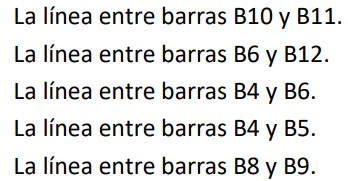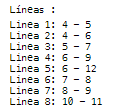

desconexiones = [2 1 7];
pasos = [4 -4; 2 -3; 3 -4];
cx = 1;
for i = 1:length(desconexiones)
    datos_linea_aux = datos_linea;
    datos_linea_aux(desconexiones(i),:) = [];
    [y_barra, r2p, r3p] = Matriz_Ybarra3(datos_linea_aux,n,datos_trafos,pasos(i,:));
    [V, delta, count, datos_potencia_PC_des] = Newton_Raphson(y_barra, datos_potencia_PC, datos_linea_aux, Sb, "normal", 1e-3);
    [PS_out, flujos, perdidas] = Flujos(V, delta, y_barra, datos_potencia_PC_des, datos_linea_aux, datos_trafos, r2p, r3p, Sb);
    %table2latex(PS_out, sprintf('PS_Contin_%d',cx))
    %table2latex(flujos, sprintf('flujos_Contin_%d',cx))
    cx = cx + 1;
end

clc
pasos = [];
count = 1;
for i = 3:length(LTC(:,1))
    if i == 3
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(1,1)), ' - ', num2str(LTC(2,1)), ' - ', num2str(LTC(3,1)), '? \n'];
    else
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(i,1)), ' - ', num2str(LTC(i,2)), '? \n'];
    end
    Q2 = input(ltc);
    pasos(count) = Q2;
    count = count+1;
end    
datos_linea_aux = datos_linea;
datos_linea_aux(:,end) = datos_linea_aux(:,end)*10; 
datos_linea_aux(8,:) = [];
datos_potencia_PC_rec = [2  0 false false false false 0 0 1.025 0;
                         1  1 (350e6)*0.77 false false false -100*Sb 100*Sb 1.04 0; 
                         3  1 (110e6)*0.76 false false false -100*Sb 100*Sb 1.025 0; 
                         4  2 false false false false false false 1 0; 
                         5  2 false false (150e6)*0.7 (80e6)*0.7 false false 1 0; 
                         6  1 false false (150e6)*0.7 (60e6)*0.7 -15e6 80e6 1 0; 
                         7  2 false false false false false false 1 0; 
                         8  2 false false (200e6)*0.7 (70e6)*0.7 false false 1 0; 
                         9  2 false false false false false false 1 0; 
                         10 2 false false (60e6)*0.6 (25e6)*0.6 false false 1 0; 
                         11 2 false false (60e6)*0.6 (20e6)*0.6 false false 1 0; 
                         12 2 false false (80e6)*0.6 (40e6)*0.6 false false 1 0];

                                          
[y_barra, r2p, r3p] = Matriz_Ybarra3(datos_linea_aux,n,datos_trafos,pasos);
[V, delta, count, datos_potencia_PC_des] = Newton_Raphson(y_barra, datos_potencia_PC_rec, datos_linea_aux, Sb, "NRDR", 1e-3);
[PS_out, flujos, perdidas] = Flujos(V, delta, y_barra, datos_potencia_PC_des, datos_linea_aux, datos_trafos, r2p, r3p, Sb)

PS_out = 12×7 table
    Barras       V       del_grados        Pg             Qg          Pd      Qd 
    ______    _______    __________    ___________    ___________    ____    ____

       2        1.025            0          1.2874        -1.6095       0       0
       1         1.04       37.576           2.695        -2.1617       0       0
       3        1.025      -27.969           0.836        -1.0794       0       0
       4       1.0547      -0.8309     -5.6861e-05    -8.6592e-07       0       0
       5       1.1185     -0.24906     -4.7071e-06     1.2282e-05    1.05    0.56
       6       1.0302      -6.7657      0.00027011       -0.78019    1.05    0.42
       7       1.1512       1.1144     -1.5958e-05     -2.265e-05       0       0
   

flujos = 20×6 table
    f1    f2       P           Q         Sabs       Sang  
    __    __    ________    ________    _______    _______

     4     5    -0.31488     -1.3303     1.3671    -103.32
     4     6      1.2422    -0.49622     1.3377    -21.775
     5     7     -1.3738     -1.1283     1.7777     -140.6
     6     9    -0.68962    -0.67565    0.96544    -135.59
     6    12     0.85835    0.043822    0.85947     2.9226
     7     8      1.2993     -3.0782     3.3412    -67.115
     8     9    -0.11753      0.6808    0.69087     99.795
     2     7       2.695     -2.1617     3.4549    -38.734
     3     9       0.836     -1.0794     1.3653    -52.243
    11    12    -0.36037    -0.12045    0.37996    -161.52
     5     4     0.32377     0.56828    0.65404     60.329
     6  

perdidas = 10×4 table
    L1    L2        Pp            Qp    
    __    __    ___________    _________

     4     5        0.63864       1.8986
     4     6        -2.4607    -0.072138
     5     7         2.7694        1.493
     6     9         1.3999      0.62155
     6    12        -1.6989     -0.42063
     7     8        -2.5818       1.9074
     8     9        0.24318      -1.8481
     2     7    -8.8818e-16     -0.55178
     3     9     1.1102e-16     -0.14194
    11    12     1.2768e-15    -0.015766


**CARGA MODIFICADA**

desconexiones = [2 1 7];
pasos = [3 -3; 2 -5; 2 -3];
cx = 1;
for i = 1:length(desconexiones)
    datos_linea_aux = datos_linea;
    datos_linea_aux(desconexiones(i),:) = [];
    if i == 1
        [y_barra, r2p, r3p] = Matriz_Ybarra3(datos_linea_aux,n,datos_trafos,pasos(i,:));
        [V, delta, count, datos_potencia_BC_des] = Newton_Raphson(y_barra, datos_potencia_BC, datos_linea_aux, Sb, "normal", 1e-3);
        [PS_out, flujos, perdidas] = Flujos(V, delta, y_barra, datos_potencia_BC_des, datos_linea_aux, datos_trafos, r2p, r3p, Sb);
    else
        [y_barra, r2p, r3p] = Matriz_Ybarra3(datos_linea_aux,n,datos_trafos,pasos(i,:));
        [V, delta, count, datos_potencia_MC_des] = Newton_Raphson(y_barra, datos_potencia_MC, datos_linea_aux, Sb, "normal", 1e-3);
        [PS_out, flujos, perdidas] = Flujos(V, delta, y_barra, datos_potencia_MC_des, datos_linea_aux, datos_trafos, r2p, r3p, Sb);
    end    
    %table2latex(PS_out, sprintf('PS_Contin_%d',cx))0
    %table2latex(flujos, sprintf('flujos_Contin_%d',cx))
    cx = cx + 1;
end

   **FALLAS**

clc
pasos = [];
count = 1;
for i = 3:length(LTC(:,1))
    if i == 3
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(1,1)), ' - ', num2str(LTC(2,1)), ' - ', num2str(LTC(3,1)), '? \n'];
    else
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(i,1)), ' - ', num2str(LTC(i,2)), '? \n'];
    end
    Q2 = input(ltc);
    pasos(count) = Q2;
    count = count+1;
end
%conexiones -> barra1 barra2 conP conS 
% Y : 1 - Delta :2
conexiones = [1 4 1 1 1 0;
              1 10 1 2 1 0;
              4 10 1 2 1 1;
              2 7 1 2 1 0;
              3 9 1 2 1 0;
              11 12 1 2 1 0];

Recsub0 = [1 1j*0.11; 
           2 1j*0.08; 
           3 1j*0.06];
       
Recsub1 = [1 1j*0.28; 
           2 1j*0.22; 
           3 1j*0.2];

datos_linea_0 = [4 5 0.01 1j*0.068 0; 
                 4 6 0.017 1j*0.092 0; 
                 5 7 0.011308 1j*0.02832 0; 
                 6 9 0.039 1j*0.1738 0; 
                 6 12 0.023 1j*0.18 0; 
                 7 8 0.008477 1j*0.057522 0; 
                 8 9 0.0119 1j*0.1008 0; 
                 10 11 0.031 1j*0.123 0];
             
datos_linea_0(:,3) = real(2.5*sum(datos_linea_0(3:4),2));
datos_linea_0(:,4) = 1j*imag(2.5*sum(datos_linea_0(3:4),2));
                     
y_barra0 = Matriz_Ybarra3(datos_linea_0,n,datos_trafos,pasos);
y_barra1 = Matriz_Ybarra3(datos_linea,n,datos_trafos,pasos);

Ifallas = [];
Vfallas = [];

Vzones = [16.5e3; 18e3; 13.8e3; 230e3; 230e3; 230e3;
          230e3; 230e3; 230e3; 34.5e3; 34.5e3; 230e3];

Izones = Sb./(sqrt(3)*Vzones);
Scap = [];

%fallas = {'Linea Tierra';'Linea Tierra';'Doble linea a Tierra'; 'trifásica'};

for i = 1:n 
    for j = 1:4
        %datos prefalla -> Vf nfalla tipofalla Zf
        datos_prefalla = [1 i j 0];
        [Vs, Is, Ss] = Fallas(y_barra0, y_barra1, conexiones, datos_prefalla, Recsub0, Recsub1);     
        Vfallas(j,:,i) = Vs;
        Ifallas(j,:,i) = Is;
    end 
    xlswrite('fallas_r.xlsx',cellfun(@num2str , num2cell([Vfallas(:,:,i), Ifallas(:,:,i)]) , 'UniformOutput', false),i)
    Scap(i,1) = sqrt(3)*Vzones(i)*max(max(Ifallas(:,:,i),[],2))*Izones(i);
end

Bar = (1:12)';
xlswrite('fallas_r.xlsx',cellfun(@num2str , num2cell([Bar, abs(Scap)./(1e6)]) , 'UniformOutput', false),13)